clf;
clear;

tilted = imread("../images/tilted.PNG");
[M,N,~] = size(tilted)

M = 1099

N = 929

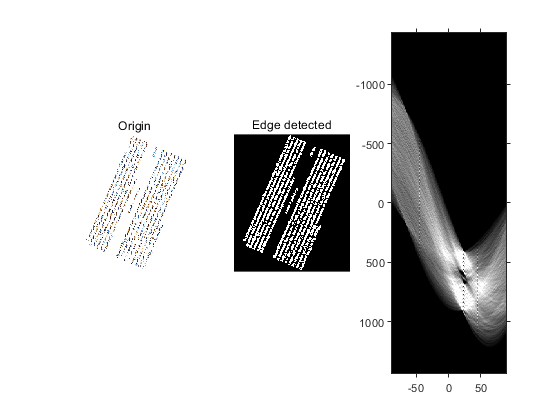

subplot(1,3,1);
imshow(tilted);title('Origin');

% Sobel Mask
sobel_x = [-1 0 1; -2 0 2; -1 0 1];
sobel_y = [-1 -2 -1; 0 0 0; 1 2 1];
tilted_double = double(im2gray(tilted));
tilted_edge = zeros(M,N);
for i = 1:M-2
    for j = 1:N-2
        tmp_x = sobel_x.*tilted_double(i:i+2,j:j+2);
        tmp_y = sobel_y.*tilted_double(i:i+2,j:j+2);
        tmp_x = sum(tmp_x(:));
        tmp_y = sum(tmp_y(:));
        tilted_edge(i+1,j+1) = sqrt(tmp_x^2 + tmp_y^2);
    end
end
% [H, theta, rho] = hough(uint8(tilted_edge)); % check
[H, theta, rho] = my_hough(uint8(tilted_edge));

subplot(1,3,2);
imshow(tilted_edge);title('Edge detected');
subplot(1,3,3);
imshow(imadjust(rescale(H)),'XData',theta,'YData',rho,'InitialMagnification','fit');
axis on, axis normal;


% find angle
H_list = H(:);
[new,ind] = sort(H_list,'descend');
[~,angle] = find(H==new(1))

angle = 114

angle = angle-180

angle = -66

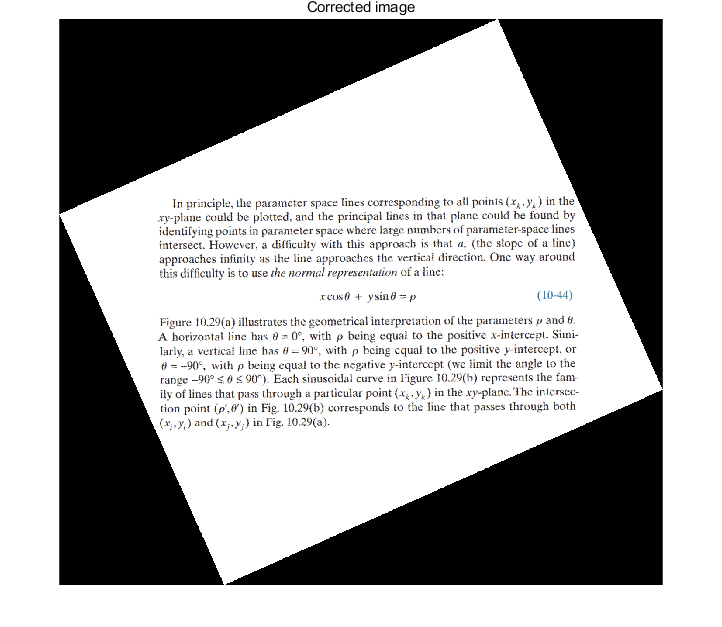

F = imrotate(tilted,angle(1));

figure;
imshow(F);title('Corrected image');

function [H, theta, rho] = my_hough(image)
    [M,N] = size(image);
    
    theta = linspace(-90, 0, 91);
    theta = [theta(2:end) -fliplr(theta(1:end-1))];
    
    D = ceil(sqrt((M-1)^2 + (N-1)^2));
    nrho = 2*D + 1;
    rho = linspace(-D, D, nrho);
    H = zeros(2*D, length(theta));

    for x = 1:M
        for y = 1:N
            if image(x, y)
                for k = 1:length(theta)
                    t = theta(k)*pi/180;
                    r = round((y-1)*cos(t)+(x-1)*sin(t))+D;
                    H(r, k) = H(r, k)+1;
                end
            end
        end
    end
end